%Using the Matlab Symbolic Toolbox to solve for properties of parametric
%curves
clc, clear all

%For this demo code, we will solve for the parametric circle that is
%presented in Robo Night 1

%First we must define the symbolic variables we will being using
syms u a

%Define the equation for the parametric circle. For clarity, I am first 
%creating individual equations for r in the i, j, and k direction, 
%then packing them in one vector. In this case, we are
%creating a 1x3 vector that has symbolic equations for the i, j, and k
%components of the equation, respectively. Note that the k component in
%this case is just equal to 0. We use 0*u because if we substitute a vector
%of numerical values in for the symbolic u at a later time, the dimensions
%of the vector will be consistent.

beta = 0.3;

ri=4*0.3960*cos(2.65*(beta*u + 1.4));
rj=-4*0.99*sin(beta*u+1.4);
rk=0*u;
r=[ri,rj,rk];

% assumptions to simplify
assume(u,{'real','positive'})

% ---- FIND T HAT ----
dr=diff(r,u);
T_hat_ugly=dr./norm(dr);
T_hat=simplify(T_hat_ugly)

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}^{2}} \end{array}$$


% ---- FIND UNIT NORMAL VECTOR----
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\left(290175\,\sigma_{7}+421350\,\sigma_{6}+131175\,\sigma_{5}\right)}{\sigma_{1}} & \frac{337080\,\sigma_{4}+615171\,\sigma_{3}+278091\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=159\,\sqrt{2500\,{\left(73\,\sigma_{7}+106\,\sigma_{6}+33\,\sigma_{5}\right)}^{2}+2809\,{\left(40\,\sigma_{4}+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{189\,u}{100}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{129\,u}{100}+\frac{301}{50}\right)\\ \sigma_{4}=\sin\left(\frac{3\,u}{10}+\frac{7}{5}\right)\\ \sigma_{5}=\cos\left(\frac{279\,u}{200}+\frac{651}{100}\right)\\ \sigma_{6}=\cos\left(\frac{159\,u}{200}+\frac{371}{100}\right)\\ \sigma_{7}=\cos\left(\frac{39\,u}{200}+\frac{91}{100}\right) \end{array}$$


% ---- FIND UNIT BINORMAL VECTOR----
B_hat=cross(T_hat,N_hat);
B_hat=simplify(B_hat)

$$B\_hat = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{91250\,\cos\left(\frac{21\,u}{200}+\frac{49}{100}\right)+\frac{764917\,\cos\left(\frac{99\,u}{200}+\frac{231}{100}\right)}{2}+\frac{327837\,\cos\left(\frac{219\,u}{200}+\frac{511}{100}\right)}{2}+41250\,\cos\left(\frac{339\,u}{200}+\frac{791}{100}\right)-\frac{205057\,\cos\left(\frac{417\,u}{200}+\frac{973}{100}\right)}{2}-\frac{92697\,\cos\left(\frac{537\,u}{200}+\frac{1253}{100}\right)}{2}}{\sqrt{2500\,{\cos\left(\sigma_{2}\right)}^{2}+2809\,{\sin\left(\sigma_{1}\right)}^{2}}\,\sqrt{2500\,{\left(73\,\cos\left(\frac{39\,u}{200}+\frac{91}{100}\right)+106\,\cos\left(\sigma_{1}\right)+33\,\cos\left(\frac{279\,u}{200}+\frac{651}{100}\right)\right)}^{2}+2809\,{\left(40\,\sin\left(\sigma_{2}\right)+73\,\sin\left(\frac{129\,u}{100}+\frac{301}{50}\right)+33\,\sin\left(\frac{189\,u}{100}+\frac{441}{50}\right)\right)}^{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{159\,u}{200}+\frac{371}{100}\\ \sigma_{2}=\frac{3\,u}{10}+\frac{7}{5} \end{array}$$


% ---- FIND CURVATURE ----
kappa=norm(dT_hat)/norm(dr);
kappa=simplify(kappa)

$$kappa = \begin{array}{l} \frac{165625\,\sqrt{2}\,\sqrt{2500\,{\left(73\,\cos\left(\frac{39\,u}{200}+\frac{91}{100}\right)+106\,\cos\left(\sigma_{1}\right)+33\,\cos\left(\frac{279\,u}{200}+\frac{651}{100}\right)\right)}^{2}+2809\,{\left(40\,\sin\left(\sigma_{2}\right)+73\,\sin\left(\frac{129\,u}{100}+\frac{301}{50}\right)+33\,\sin\left(\frac{189\,u}{100}+\frac{441}{50}\right)\right)}^{2}}}{198\,\sqrt{2500\,{\cos\left(\sigma_{2}\right)}^{2}+2809\,{\sin\left(\sigma_{1}\right)}^{2}}\,{\left(2500\,\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)+5309\right)}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{159\,u}{200}+\frac{371}{100}\\ \sigma_{2}=\frac{3\,u}{10}+\frac{7}{5} \end{array}$$


% ---- FIND TORSION ----
tau=-dot(N_hat,(diff(B_hat,u)/norm(dr)))

$$tau = 0$$


% ---- FIND VELOCITY ----
v = simplify(dr)

$$v = \left(\begin{array}{ccc} -\frac{15741\,\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}{12500} & -\frac{297\,\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}{250} & 0 \end{array}\right)$$

speed = simplify(norm(v))

$$speed = \frac{297\,\sqrt{2500\,{\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}^{2}}}{12500}$$


% ---- FIND ANGULAR VELOCITY ----
angular_velocity = simplify(cross(T_hat,diff(T_hat,u)))

$$angular\_velocity = \left(\begin{array}{ccc} 0 & 0 & -\frac{11607\,\cos\left(\frac{99\,u}{200}+\frac{231}{100}\right)+5247\,\cos\left(\frac{219\,u}{200}+\frac{511}{100}\right)}{10000\,\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right)-11236\,\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)+21236} \end{array}\right)$$


% ---- FIND ACCELERATION ----
accel = simplify(diff(v, u))

$$accel = \left(\begin{array}{ccc} -\frac{2502819\,\cos\left(\frac{159\,u}{200}+\frac{371}{100}\right)}{2500000} & \frac{891\,\sin\left(\frac{3\,u}{10}+\frac{7}{5}\right)}{2500} & 0 \end{array}\right)$$

% decompose accel in terms of % tangent
aT = simplify(dot(accel, T_hat))

$$aT = -\frac{\sqrt{2}\,\left(44550000\,\sin\left(\frac{3\,u}{5}+\frac{14}{5}\right)-132649407\,\sin\left(\frac{159\,u}{100}+\frac{371}{50}\right)\right)}{5000000\,\sqrt{2500\,\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)+5309}}$$

aN = simplify(dot(accel, N_hat))

$$aN = \frac{47223\,\left(2409\,\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right)+\frac{5329\,\cos\left(\frac{99\,u}{100}+\frac{231}{50}\right)}{2}+2409\,\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)+\frac{1089\,\cos\left(\frac{219\,u}{100}+\frac{511}{50}\right)}{2}+3209\right)}{50000\,\sqrt{2500\,{\left(73\,\cos\left(\frac{39\,u}{200}+\frac{91}{100}\right)+106\,\cos\left(\frac{159\,u}{200}+\frac{371}{100}\right)+33\,\cos\left(\frac{279\,u}{200}+\frac{651}{100}\right)\right)}^{2}+2809\,{\left(40\,\sin\left(\frac{3\,u}{10}+\frac{7}{5}\right)+73\,\sin\left(\frac{129\,u}{100}+\frac{301}{50}\right)+33\,\sin\left(\frac{189\,u}{100}+\frac{441}{50}\right)\right)}^{2}}}$$


% ---- FIND LEFT WHEEL ----
d = 0.235

d = 0.2350

v_left_wheel = simplify(v - (angular_velocity * d)/2)

$$v\_left\_wheel = \left(\begin{array}{ccc} -\frac{15741\,\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}{12500} & -\frac{297\,\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}{250} & \frac{47\,\left(11607\,\cos\left(\frac{99\,u}{200}+\frac{231}{100}\right)+5247\,\cos\left(\frac{219\,u}{200}+\frac{511}{100}\right)\right)}{400\,\left(10000\,\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right)-11236\,\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)+21236\right)} \end{array}\right)$$

v_right_wheel = simplify(v + (angular_velocity * d)/2)

$$v\_right\_wheel = \left(\begin{array}{ccc} -\frac{15741\,\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}{12500} & -\frac{297\,\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}{250} & -\frac{47\,\left(11607\,\cos\left(\frac{99\,u}{200}+\frac{231}{100}\right)+5247\,\cos\left(\frac{219\,u}{200}+\frac{511}{100}\right)\right)}{400\,\left(10000\,\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right)-11236\,\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)+21236\right)} \end{array}\right)$$

u_num = linspace(0,3.2,100); % define a set of evenly spaced points between 0 and 2*pi

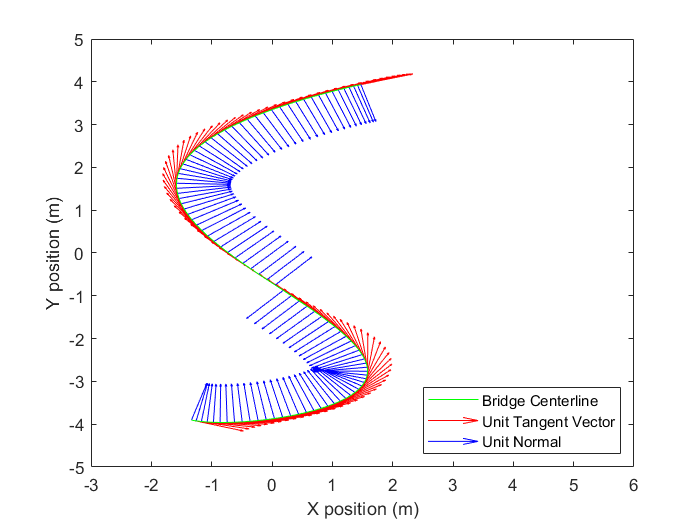

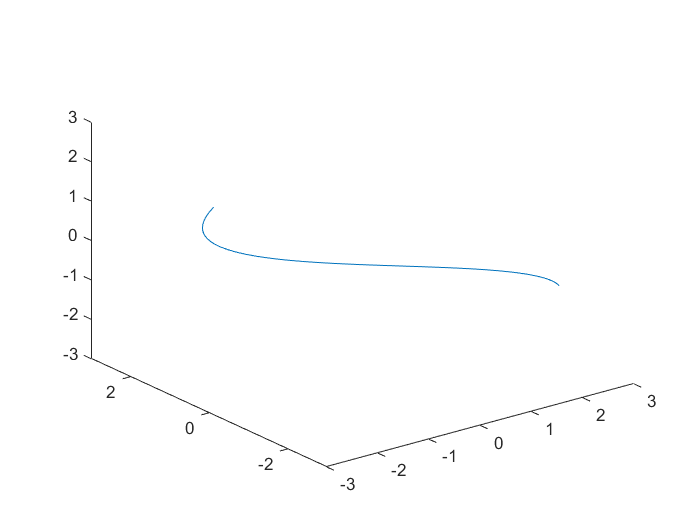

clf;
%we will also convert to a number of type double
for n=1:length(u_num)
    r_num(n,:)=double(subs(r,[u],[u_num(n)]));
    T_hat_num(n,:)=double(subs(T_hat,[u],[u_num(n)]));
    N_hat_num(n,:)=double(subs(N_hat,[u],[u_num(n)]));
    B_hat_num(n,:)=double(subs(B_hat,[u],[u_num(n)]));
    
    %we can also plot this using the quiver3 function
    plot(r_num(:,1),r_num(:,2),'g'),axis([-3 6 -5 5]),hold on % plot the entire curve
    quiver(r_num(n,1),r_num(n,2),T_hat_num(n,1),T_hat_num(n,2),'r') % plot the unit tangent
    quiver(r_num(n,1),r_num(n,2),N_hat_num(n,1),N_hat_num(n,2),'b') % plot the unit normal
    drawnow % force the graphic to update as it goes
end
xlabel('X position (m)')
ylabel('Y position (m)')
legend('Bridge Centerline', 'Unit Tangent Vector', 'Unit Normal','Location','southeast')

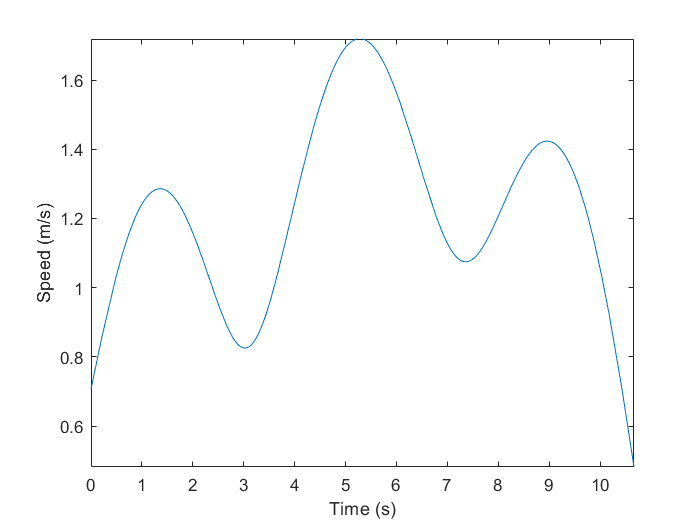

clf;
fplot(speed,[0 3.2/beta])
xlabel('Time (s)')
ylabel('Speed (m/s)')

for n=1:length(u_num)
    r_num(n,:)=double(subs(r,[u],[u_num(n)]));
    speed_num(n,:)=double(subs(speed,[u],[u_num(n)]));
    angular_velocity_num(n,:)=double(subs(angular_velocity,[u],[u_num(n)]));
    
    %we can also plot this using the quiver3 function
    plot(r_num(:,1),r_num(:,2),'g'),axis([-3 6 -5 5]),hold on % plot the entire curve
    
    drawnow % force the graphic to update as it goes
end